# kNN: regions get smoother when increasing k

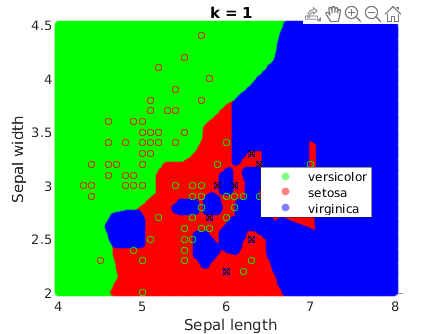

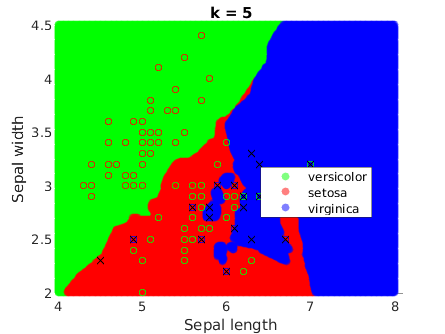

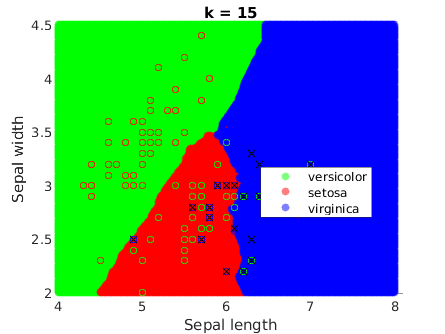

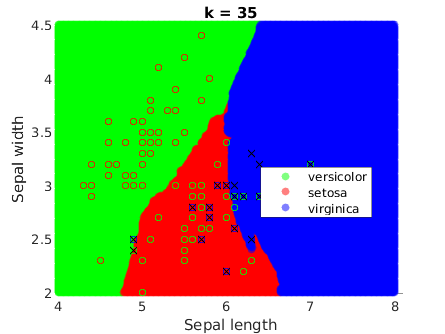

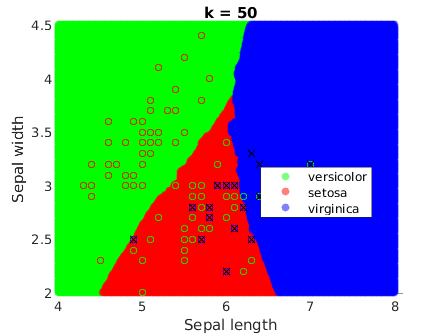

load fisheriris

% Define custom colors for the species
colors = [0 1 0; 1 0 0; 0 0 1];
face_alpha = 0.5;

k_values = [1, 5, 15, 35, 50];

for k_idx = 1:length(k_values)
    k = k_values(k_idx);

    % Train kNN classifier
    knn = fitcknn(meas(:,1:2), species, 'NumNeighbors', k);
    knnClass = resubPredict(knn);

    % Visualize the decision regions
    f = figure;
    [x, y] = meshgrid(4:.01:8, 2:.01:4.5);
    x = x(:);
    y = y(:);
    j = predict(knn, [x y]);

    % Loop through unique species and plot points with custom colors and transparency
    unique_species = unique(j);
    for i = 1:length(unique_species)
        scatter(x(strcmp(j, unique_species{i})), y(strcmp(j, unique_species{i})), [], colors(i,:), 'o', 'filled', 'MarkerFaceAlpha', face_alpha);
        hold on;
    end

    % Plot the original dataset on top of the decision regions
    gscatter(meas(:,1), meas(:,2), species, 'rgb', 'o', 5);

    % Plot misclassified points
    bad_knn = ~strcmp(knnClass, species);
    plot(meas(bad_knn, 1), meas(bad_knn, 2), 'kx');

    hold off;

    % Set title and labels
    title(sprintf('k = %d', k));
    xlabel('Sepal length');
    ylabel('Sepal width');
    legend('versicolor','setosa','virginica')
end